### Problem Definition

Given a set of assets corresponding to expected returns and covariances, along with a risk factor and budget, we seek a subset of assets such that the resulting weighted mean-variance is maximized. 

% Covariance between assets 
params.sigma = [ 0.0064 0.00408 0.00192 0;
    0.00408 0.0289 0.0204 0.0119;
    0.00192 0.0204 0.0576 0.0336;
    0 0.0119 0.0336 0.1225 ];

% Expected returns for assets
params.mu = [0.05; 0.1; 0.12; 0.18];

% Risk appetite 
params.q = 0.5;

% Budget
params.B = 3;

% Penality for budget
params.lambda = 10;

% Number of qubits 
params.N = length(params.mu);

**VQE-CVaR Parameters: **

To reduce compilation overhead, an ansatz is used that respects the native gate set and connectivity of the Aspen-M-3 device. 

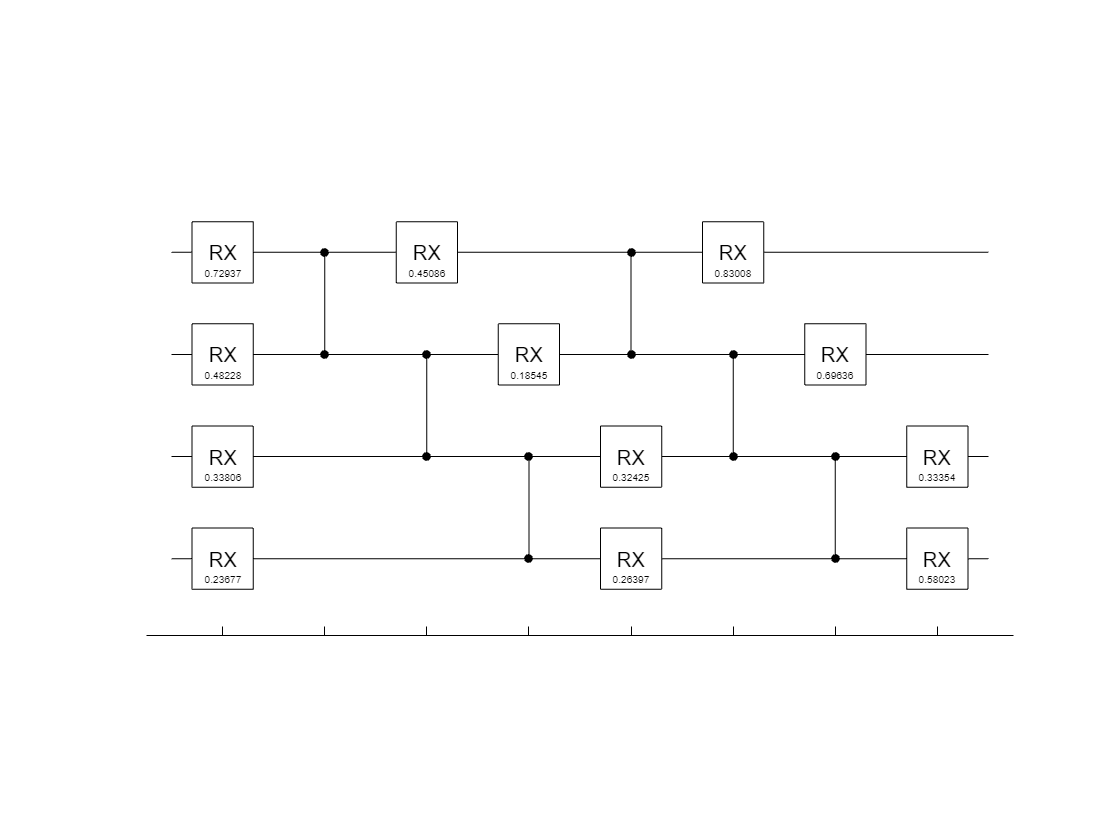

% Number of repeated entangling blocks
params.ansatzDepth = 2;

% Number of learnable angles for the ansatz circuit
numAngles = params.N*(params.ansatzDepth+1);

% Number of simulated runs
params.numSimShots = 1000; 

% Plot the ansatz with arbitrary angles to view its structure
randAnsatz = buildAnsatz(rand(numAngles, 1), params.N);
plot(randAnsatz)

### Classical Solution

Evaluate all possible states to determine the optimal bitstring solution 

allStates = dec2bin(0:2^params.N-1);
allValues = portfolioObjective(allStates, params);
[fmin, idx] = min(allValues);
xsol = allStates(idx, :)

xsol = '1101'

fmin

fmin = -0.2351

### Simulate the Variational Quantum Eigensolver 

The objective function for the optimizer takes the angles and simulates an iteration of the VQE-CVaR routine. 

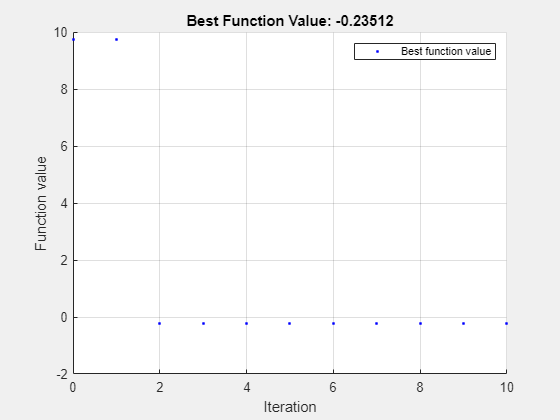

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


objFcn = @(theta) simVQECVAR(theta, params);

options = optimoptions("surrogateopt", "MaxFunctionEvaluations",10);

lb = repmat(-pi, numAngles, 1); 
ub = repmat(pi, numAngles, 1);
[optAngles, ~] = surrogateopt(objFcn,lb,ub,[],[],[],[],[],options);

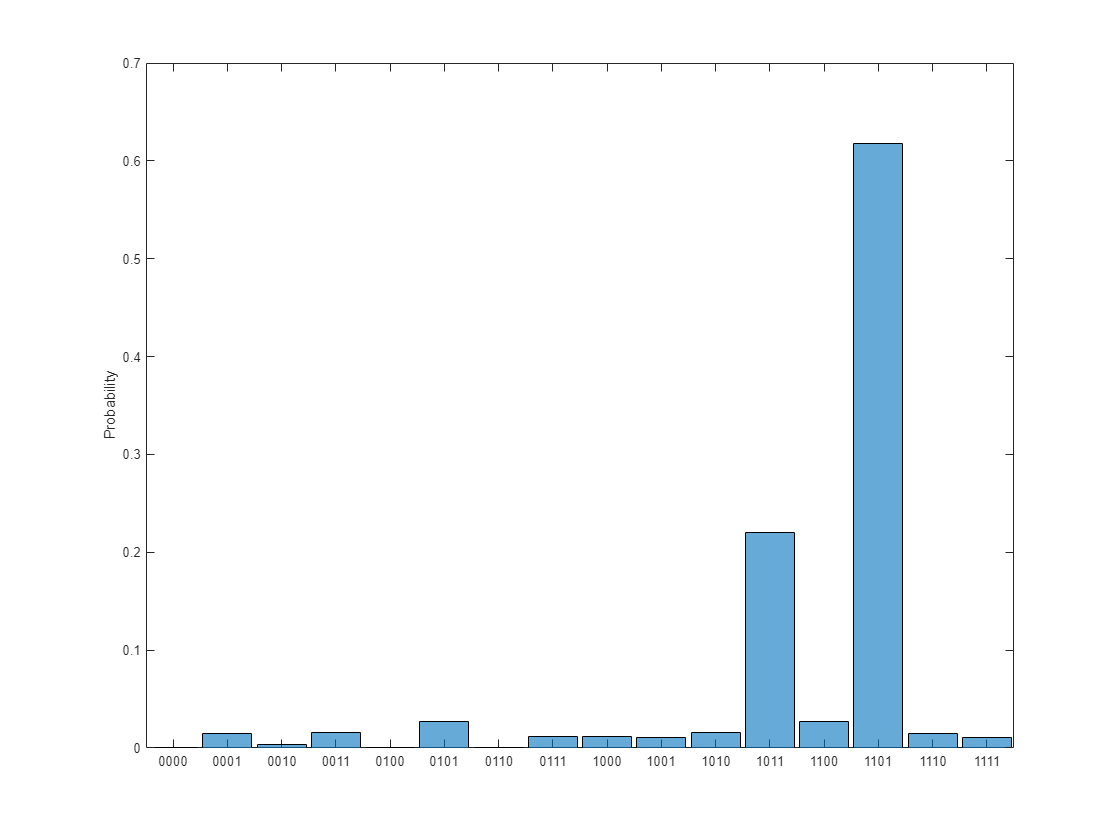

optAnsatz = buildAnsatz(optAngles, params.N);
sv = simulate(optAnsatz);
figure
histogram(sv)

### Run the Final Circuit on Hardware

Run the optimized ansatz circuit on the Aspen-M-3 device provided through AWS Braket.

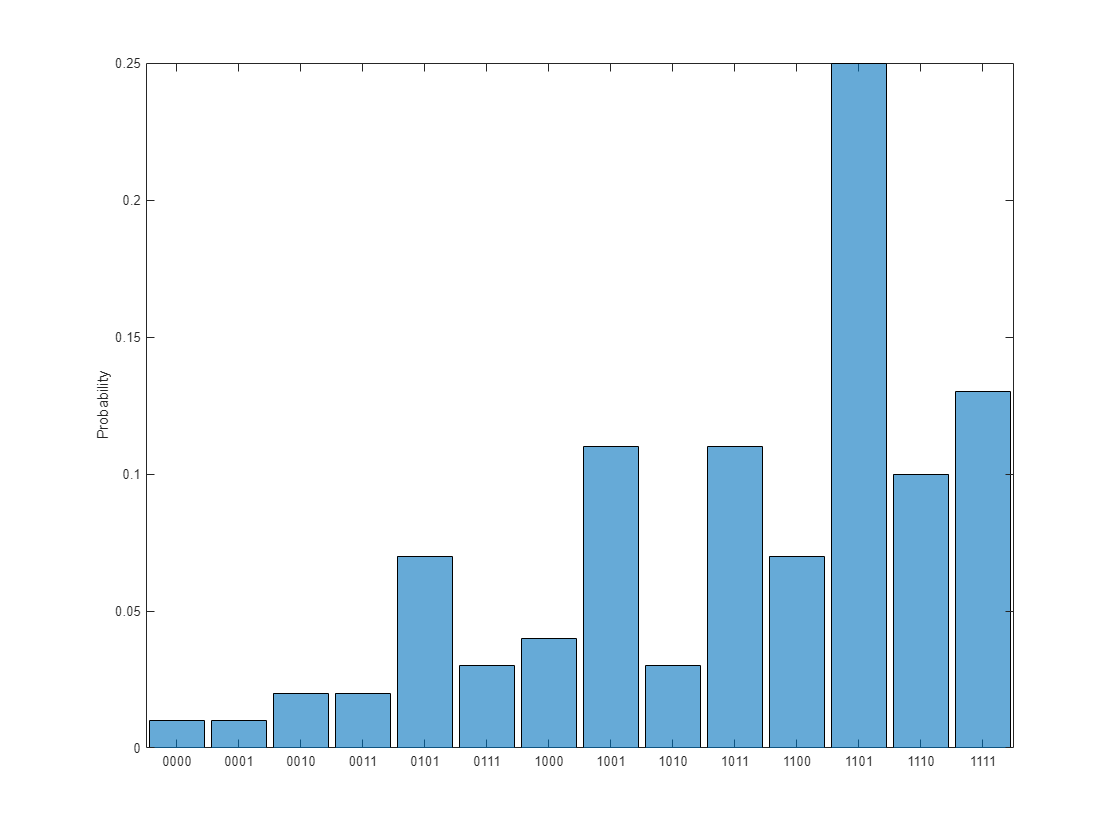

% device = quantum.backend.QuantumDeviceAWS("Aspen-M-3");
% task = run(optAnsatz, device, NumShots=100);
% result = fetchOutput(task);
% histogram(result)

% Load the previously completed task
task = quantum.backend.QuantumTaskAWS("arn:aws:braket:us-west-1:532578954166:quantum-task/b63d7d66-5c6d-4a50-8b0c-a018dfa7c782");
result = fetchOutput(task);
histogram(result)

function values = portfolioObjective(bitstrings, params)
% Mean-Variance Portfolio Objective Function 
N = size(bitstrings, 1);
values = zeros(N,1);
for idx = 1:N
    x = double(bitstrings(idx,:)=='1')';
    values(idx) = params.q*(x'*params.sigma*x) - (params.mu'*x) + params.lambda*(sum(x)-params.B)^2;
end 
end 


function ansatz = buildAnsatz(angles, N)

% Linear pattern
entgBlk = czGate(1:N-1, 2:N);

angles = reshape(angles, N, []);

% Assemble alternating layers of rotations and entangling blocks
gates = rxGate(1:N, angles(:,1));
for p = 2:size(angles, 2)
gates = [gates; entgBlk; rxGate(1:N, angles(:,p))];
end
ansatz = quantumCircuit(gates);
end


function value = simVQECVAR(angles, params)  

% Construct and simulate the variational circuit 
ansatz = buildAnsatz(angles, params.N);
qState = simulate(ansatz);

% Sample and query the state probabilities  
qMeasurement = randsample(qState, params.numSimShots);
[states, probs] = querystates(qMeasurement);

% Sort the probabilities by the objective value
[values,sortperm] = sort(portfolioObjective(char(states), params));
probs = probs(sortperm);

% CVaR cutoff 
params.alpha = 0.1;

% Compute CVaR over the low tail of the distribution
cutoff = nnz(cumsum(probs) < params.alpha);
cvarProbs = probs(1:cutoff);
cvarProbs(end+1) = params.alpha - sum(cvarProbs);
value = dot(cvarProbs, values(1:cutoff+1))/params.alpha;

end